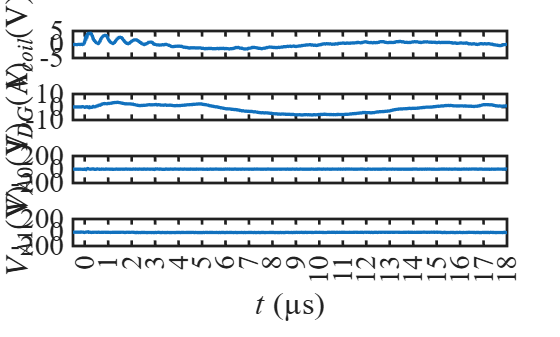

clear; clc;
global Folder_dir

% =========================================================
% Configuration
% =========================================================
LW = 2.5;

CH1_LIM = [-5 5];
CH2_LIM = [-10 10];
CH3_LIM = [-200 200];
CH4_LIM = [-200 200];

CH = [-0.5 18];
My_XTicks = 0:1:18;
FFT_ylim = [0 0.5];

Dir     = 'DAY 4-9-2025';
Ex      = 'Ex02';
Scope   = '';   % data files sit directly in DAY*/ExNN/
DataLog = 'DataLog_0000_Analog.csv';

Folder_dir = fileparts(matlab.desktop.editor.getActiveFilename);
scope1 = fullfile(Folder_dir, Dir, Ex, Scope, DataLog);

% =========================================================
% Data Acquisition
% =========================================================
try
    data = readtable(scope1);

    time = table2array(data(17:125016, 1));
    time = (time - time(1)) - 2E-6;

    CH1  = table2array(data(17:125016, 2));
    CH2  = table2array(data(17:125016, 3));
    CH3  = table2array(data(17:125016, 4));
    CH4  = table2array(data(17:125016, 5));
    MATH = table2array(data(17:125016, 6));

catch
    disp('CSV file not found. Generating simulated data.');

    time = linspace(0, 20e-6, 100000)';

    CH1 = 0.5 * randn(size(time));
    CH2 = 0.5 * randn(size(time));
    CH3 = 5 + 0.2 * randn(size(time)) + ...
          0.1 * sin(2*pi*1e6*time);
    CH4 = 5 + 0.4 * randn(size(time)) + ...
          0.2 * sin(2*pi*5e5*time);
end

% =========================================================
% Time-Domain Analysis
% =========================================================
figure('Name', 'Time Domain Signals');
tiledlayout(4, 1, 'TileSpacing', 'tight');

y_labels = gobjects(4, 1);

nexttile;
plot(time*1E6, CH1, 'LineWidth', LW);
y_labels(1) = ylabel('$V_{coil}\mathrm{(V)}$', ...
    'Interpreter', 'latex');

xticks(My_XTicks);
xticklabels([]);
ylim(CH1_LIM);
xlim(CH);

set(gca, 'FontSize', 22, ...
         'FontName', 'Times New Roman', ...
         'LineWidth', 2.0);

nexttile;
plot(time*1E6, CH2, 'LineWidth', LW);
y_labels(2) = ylabel('$I_{DG}\mathrm{(A)}$', ...
    'Interpreter', 'latex');

xticks(My_XTicks);
xticklabels([]);
ylim(CH2_LIM);
xlim(CH);

set(gca, 'FontSize', 22, ...
         'FontName', 'Times New Roman', ...
         'LineWidth', 2.0);

nexttile;
plot(time*1E6, CH3, 'LineWidth', LW);
y_labels(3) = ylabel('$V_{A0}\mathrm{(V)}$', ...
    'Interpreter', 'latex');

xticks(My_XTicks);
xticklabels([]);
ylim(CH3_LIM);
xlim(CH);

set(gca, 'FontSize', 22, ...
         'FontName', 'Times New Roman', ...
         'LineWidth', 2.0);

nexttile;
plot(time*1E6, CH4, 'LineWidth', LW);
y_labels(4) = ylabel('$V_{A1}\mathrm{(V)}$', ...
    'Interpreter', 'latex');

xlabel(['{\itt} (', char(181), 's)'], 'Interpreter', 'tex');

xticks(My_XTicks);
ylim(CH4_LIM);
xlim(CH);

set(gca, 'FontSize', 22, ...
         'FontName', 'Times New Roman', ...
         'LineWidth', 2.0);

% Align Y-axis labels across all subplots.
set(y_labels, 'Units', 'normalized');
set(y_labels, 'Position', [-0.08, 0.5, 0]);


% =========================================================
% FFT and SNR Analysis: CH3
% =========================================================
N  = length(CH3);
dt = mean(diff(time));
Fs = 1/dt;

Y_CH3  = fft(CH3);
P2_CH3 = abs(Y_CH3/N);

P1_CH3 = P2_CH3(1:floor(N/2)+1);
P1_CH3(2:end-1) = 2*P1_CH3(2:end-1);

f_CH3 = Fs*(0:floor(N/2))/N;

P_signal       = 5^2;
P_noise_CH3    = sum(P2_CH3(2:end).^2);
SNR_CH3_linear = P_signal/P_noise_CH3;
SNR_CH3_dB     = 10*log10(SNR_CH3_linear);

fprintf('=== SNR Analysis Results ===\n');

=== SNR Analysis Results ===


fprintf('CH3 SNR = %.2f dB\n', SNR_CH3_dB);

CH3 SNR = 16.20 dB



figure('Name', 'FFT and SNR Analysis');
tiledlayout(2, 1, 'TileSpacing', 'tight');

nexttile;
semilogx(f_CH3/1E6, P1_CH3, 'LineWidth', LW);

xticklabels([]);
ylabel('$A_{V_{A0}}\mathrm{(V)}$', 'Interpreter', 'latex');

xlim([1E-1 1E3]);
ylim(FFT_ylim);

grid on;

set(gca, 'FontSize', 22, ...
         'FontName', 'Times New Roman', ...
         'LineWidth', 2.0);

% =========================================================
% FFT and SNR Analysis: CH4
% =========================================================
N_CH4 = length(CH4);

Y_CH4  = fft(CH4);
P2_CH4 = abs(Y_CH4/N_CH4);

P11_CH4 = P2_CH4(1:floor(N_CH4/2)+1);
P11_CH4(2:end-1) = 2*P11_CH4(2:end-1);

f_CH4 = Fs*(0:floor(N_CH4/2))/N_CH4;

P_noise_CH4    = sum(P2_CH4(2:end).^2);
SNR_CH4_linear = P_signal/P_noise_CH4;
SNR_CH4_dB     = 10*log10(SNR_CH4_linear);

fprintf('CH4 SNR = %.2f dB\n\n', SNR_CH4_dB);

CH4 SNR = 9.55 dB



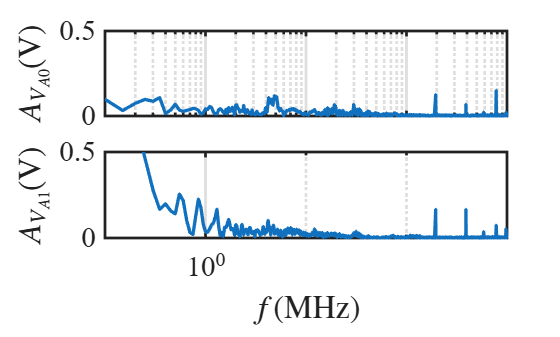


nexttile;
semilogx(f_CH4/1E6, P11_CH4, 'LineWidth', LW);

xlabel('$f\mathrm{(MHz)}$', 'Interpreter', 'latex');
ylabel('$A_{V_{A1}}\mathrm{(V)}$', 'Interpreter', 'latex');

xlim([1E-1 1E3]);
ylim(FFT_ylim);

grid on;

set(gca, 'FontSize', 22, ...
         'FontName', 'Times New Roman', ...
         'LineWidth', 2.0);